# Chapter 2, Section 3 (Part 3)

We'll share a few important theorems in this activity.

# Theorem #1

Suppose $S=\left\{\vec v_1, \vec v_2,\ldots,\vec v_n\right\}$ is a collection of linearly independent vectors. Suppose that some vector $\vec v$ can be written as a linear combination of these vectors. 


$$\vec v=c_1\vec v_1+c_2\vec v_2+\cdots+c_n\vec v_n}$$


Then the scalars unique.

**Proof:** Suppose that there is another way to write $\vec v$ as a linear combination of the vectors in $S$, such as:


$$\vec v=d_1\vec v_1+d_2\vec v_2+\cdots d_n\vec v_ $$


We can use our properties of vectors to write:


$$\begin{array}{rcl}
c_1\vec v_1+c_2\vec v_2+\cdots+c_n\vec v_n&=&d_1\vec v_1+d_2\vec v_2+\cdots+d_n\vec v_n\\
\left(c_1\vec v_1+c_2\vec v_2+\cdots+c_n\vec v_n\right)-\left(d_1\vec v_1+d_2\vec v_2+\cdots+d_n\vec v_n\right)&=&\vec 0\\
(c_1-d_1)\vec v_1+(c_2-d_2)\vec v_2+\cdots+(c_n-d_n)\vec v_n&=&0
\end{array}$$


Because our vectors $\vec v_1$, $\vec v_2$, ... , $\vec v_n$ are linearly independent, $c_1-d_1=0$, $c_2-d_2=0$, ... , $c_n-d_n=0$. Thus, $c_1=d_1$, $c_2=d_2$, ... , $c_n=d_n$, which means the scalars are unique.

# Example #1

Given that the vectors 


$$\vec v_1=\pmatrix{1\cr 2\cr -1},\qquad \vec v_2=\pmatrix{2 \cr 2 \cr 1},\qquad\text{and}\qquad \vec v_3=\pmatrix{1\cr 1\cr 1}$$


are linearly independent, find unique scalars so that


$$\vec v=\pmatrix{2\cr 0\cr 2}$$


can be written as:


$$\vec v=c_1\vec v_1+c_2\vec v_2+c_3\vec v_3$$


**Solution: ** We are given that the vectors are linearly independent, so we know that this unique linear combination exists by our theorem above. 


$$\begin{array}{rcl}
c_1\pmatrix{1\cr 2\cr -1}+c_2\pmatrix{2\cr 2\cr 1}+c_2\pmatrix{1\cr 1\cr 1}&=&\pmatrix{2\cr 0\cr 2}\\
\pmatrix{1 & 2 & 1\cr 2 & 2 & 1\cr -1 & 1 & 1}\pmatrix{c_1\cr  c_2\cr c_3}&=&\pmatrix{2\cr 0\cr 2}
\end{array}$$


Set up the augmented matrix and row reduce.


$$\pmatrix{1 & 2 & 1 & 2\cr 2 & 2 & 1 & 0\cr -1 & 1 & 1 & 2}\ \matrix{~\cr R_2-2R_1\cr R_3+R_1}\qquad\longrightarrow\qquad\pmatrix{1 & 2 & 1 & 2\cr 0 & -2 & -1 & -4\cr 0 & 3 & 2 & 4}$$


We can check this with Matlab.

A=[1 2 1 2;2 2 1 0;-1 1 1 2];
r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
A=[r1;r2-2*r1;r3+r1]

A =      1     2     1     2
     0    -2    -1    -4
     0     3     2     4


Same answer. Next,


$$\pmatrix{1 & 2 & 1 & 2\cr 0 & -2 & -1 & -4\cr 0 & 3 & 2 & 4}\ \matrix{~\cr ~\cr R_3+(3/2)R_2}\qquad\longrightarrow\qquad\pmatrix{1 & 2 & 1 & 2\cr 0 & -2 & -1 & -4\cr 0 & 0 & 1/2 & -2}$$


We can check this with Matlab.

r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
A=sym([r1;r2;r3+3/2*r2])

$$A = \left(\begin{array}{cccc} 1 & 2 & 1 & 2\\ 0 & -2 & -1 & -4\\ 0 & 0 & \frac{1}{2} & -2 \end{array}\right)$$

Same answer. Now, we have a system of three equations.


$$\begin{array}{rcl}
c_1+2c_2+c_3&=&2\\
-2c_2-c_3&=&-4\\
\frac{1}{2}c_3&=&-2
\end{array}$$


Now we will use back substitution. The last equation gives us $c_3=-4$.  Substituting $c_3=-4$ in the second equation gives us:


$$\begin{array}{rcl}
-2c_2-(-4)&=&-4\\
-2c_2+4&=&-4\\
-2c_2&=&-8\\
c_2&=&4
\end{array}$$


Substituting $c_2=4$ and $c_3=-4$ in the first equation gives us:


$$\begin{array}{rcl}
c_1+2(4)+(-4)&=&2\\
c_1+4&=&2\\
c_1&=&-2
\end{array}$$


Therefore, $c_1=-2$, $c_2=4$, and $c_3=-4$. Here is a fast way to check this answer.

A=[1 2 1 2;2 2 1 0;-1 1 1 2];
rref(A)

ans =      1     0     0    -2
     0     1     0     4
     0     0     1    -4


Note that this reduced row echelon form also tells us that $c_1=-2$, $c_2=4$, and $c_3=-4$. Now, is it true that


$$\vec v=c_1\vec v_1+c_2\vec v_2+c_3\vec v_3$$


Let's check this with Matlab (we could also check it  by hand). We should get $\vec v=(2,0,2)^T$ as an answer.

v1=[1;2;-1]; v2=[2;2;1]; v3=[1;1;1];
-2*v1+4*v2-4*v3

ans =      2
     0
     2


That's identical to the given vector $\vec v=(2,0,2)^T$, so we've done this correctly. 

# Theorem #2

Suppose $A\vec x=\vec b$ is a consistent (has an answer) $m\times n$ linear system. The solution is unique if and only if the columns of $A$ are linearly independent.

**Proof: **This is an "if and only if" statement, so we have two things we have to prove.

- If the columns of $A$ are linearly independent, then the solution is unique.

- If the solution is unique, then the columns of $A$ are linearly independent.

**Part 1: **Assume that the columns of $A$ are linearly indpendent. Now we need to show that solutions of $A\vec x=\vec b$ are unique. Let's suppose that (recall that $A$ is $m\times n$)


$$\vec x=\pmatrix{x_1\cr x_2\cr \vdots \cr x_n}\qquad\text{and}\qquad \vec y=\pmatrix{y_1\cr y_2\cr \vdots\cr y_n}$$


are two different solutions of $A\vec x=\vec b$. Then


$$\begin{array}{rcl}
A\vec x&=&\vec b\\
\left[\matrix{\vec a_1 & \vec a_2 & \cdots & \vec a_n}\right]\pmatrix{x_1\cr x_2\cr \vdots\cr x_n}&=&\vec b\\
x_1\vec a_1+x_2\vec a_2+\cdots+x_n\vec a_n&=&\vec b
\end{array}$$


and:


$$\begin{array}{rcl}
A\vec y&=&\vec b\\
\left[\matrix{\vec a_1 & \vec a_2 & \cdots & \vec a_n}\right]\pmatrix{y_1\cr y_2\cr \vdots\cr y_n}&=&\vec b\\
y_1\vec a_1+y_2\vec a_2+\cdots+y_n\vec a_n&=&\vec b
\end{array}$$


Thus, we have $x_1\vec a_1+x_2\vec a_2+\cdots+x_n\vec a_n=\vec b$ and $y_1\vec a_1+y_2\vec a_2+\cdots+y_n\vec a_n=\vec b$. But his contradicts our first theorem above that says if the vectors are independent, the scalars must be unique. Therefore, our assumption that there are two different answers is false and we're done. We've shown that the solutions must be unique.

**Part 2: ** Assume that the system $A\vec x=\vec b$ is consistent and that solutions are unique. This means that there is a unique solution $\vec v$ such that $A\vec v=\vec b$. Now we need to show that the columns of matrix $A$ are linearly independent. We will suppose that this is not true, that the are linearly dependent. That means there exists a nontrivial linear combination of the columns of $A$ so that:


$$c_1\vec a_1+c_2\vec a_2+\cdots+c_n\vec a_n=\vec 0$$


This can be written as


$$\begin{array}{rcl}
\left[\matrix{\vec a_1 & \vec a_2 & \cdots &\vec a_n}\right]\pmatrix{c_1\cr c_2\cr\vdots\cr c_n}&=&\vec 0\\
A\vec c&=&0
\end{array}$$


where $\vec c$ is a nonzero vector (not all of is elements are zero). Now we will use the property $A(\vec x+\vec y)=A\vec x+A\vec y$ to write:


$$\begin{array}{rcl}
A(\vec v+\vec c)&=&A\vec v+A\vec c\\
&=&\vec b+\vec 0\\
&=&\vec b
\end{array}$$


This means that $\vec v+\vec c$ (which is different from $\vec v$ because $\vec c\ne\vec 0$) is also a solution of $A\vec x=\vec b$. This contradicts our starting assumption that solutions of $A\vec x=\vec b$ are unique. Therefore, our assumption at the beginning that the columns of $A$ are linearly dependent is incorrect. The columns of $A$ are linearly independent. We're done. :-)

# Theorem #3

Let $A$ be a square $n \times n$ matrix. The columns of $A$ are linearly independent if and only if $\text{det}(A)\ne 0$. 

**Proof:** Again, this is an "if and only if" statement, so we have two things we need to prove.

- If the columns of $A$ are linearly independent, then $\text{det}(A)\ne 0$.

- If the $\text{det}(A)\ne 0$, then the columns of $A$ are linearly independent.

**Part 1:** Note that $A$ is a square $n\times n$ matrix. Let's assume that the columns of $A$ are linearly independent. Now, we need to show that $\text{det}(A)\ne 0$. By Theorem #2, because the columns of matrix $A$ are linearly independent, the solutions of $A\vec x=\vec 0$ are unique (where $\vec b=\vec 0$). We know that $\vec x=0$ is a solution of $A\vec x=\vec 0$, but because this is the only solution, matrix $A$ can be row reduced to the identity matrix. The only way that the only solution is $\vec x=\vec 0$ is if our reduced row echelon form looks as follows (a $3\times 3$ example):


$$\begin{array}{rcl}
\left[\matrix{A & \vec 0}\right]&\rightarrow&\left[\matrix{I & \vec 0}\right]\\
\left[\matrix{A & \vec 0}\right]&\rightarrow&\pmatrix{1 & 0 & 0 & 0\cr 0 & 1 & 0 & 0\cr 0 & 0 & 1 & 0}
\end{array}$$
 

This would give the solution $\vec x=\vec 0$. Because $A$ can be row reduced to the identity matrix, we know that $A$ is invertible. Recall that we proved in Chapter 1, Section 6, that $A$ is invertible if and only if $\text{det}(A)\ne 0$. Therefore, we have proved that $\text{det}(A)\ne 0$.

**Part 2: **We assume that $\text{det}(A)\ne 0$. We need to show that the columns of matrix $A$ are linearly independent. Using again our theorem from Chapter 1, Section 6 (if $\text{det}(A)\ne 0$, then $A$ is invertible), we know that $A$ is invertible; that is, $A^{-1}$ exists. This means that the solution of 


$$A\vec x=\vec b$$


is;


$$\vec x=A^{-1}\vec b$$


This means that solutions are unique and by our Theorem 2 above, the columns of $A$ are linearly independent. We're done. :-)

# Example #2

Given 


$$A=\pmatrix{1& 3 & 4\cr 2 & 4 & 6\cr -1 & 1 & 2}$$


determine if the system $A\vec x=\vec b$ has a unique solution.

**Solution: **By our theorems above, the system has a unique solution if the columns of $A$ are linearly independent and the columns are linearly independent if $\text{det}(A)\ne 0$. Let's calculate the determinant. We'll use the Laplace Cofactor Expansion across the first row.


$$\begin{array}{rcl}
\left|\matrix{1 & 3 & 4\cr 2 & 4 & 6\cr -1 & 1 & 2}\right|&=&1\left|\matrix{4 & 6\cr 1 & 2}\right|-3\left|\matrix{2 & 6\cr -1 & 2}\right|+4\left|\matrix{2 & 4\cr -1 & 1}\right|\\
&=&1(8-6)-3(4-(-6))+4(2-(-4))\\
&=&1(2)-3(10)+4(6)\\
&=&2-30+24\\
&=&-4
\end{array}
\end{array}$$


Let's check our work with Matlab.

A=[1 3 4;2 4 6;-1 1 2];
det(sym(A))

$$ans = -4$$

We did it correctly. Because $\text{det}(A)\ne 0$, the columns of $A$ are linearly independent. Let's verify this theorem by the definition of linear independence to show that the columns of $A$ are linearly independent.


$$\begin{array}{rcl}
c_1\pmatrix{1\cr 2\cr -1}+c_2\pmatrix{3\cr 4\cr 1}+c_3\pmatrix{4\cr 6\cr 2}&=&\pmatrix{0\cr 0\cr 0}\\
\pmatrix{1 & 3 & 4\cr 2 & 4 & 6\cr -1 & 1 & 2}\pmatrix{c_1\cr c_2\cr c_3}&=&\pmatrix{0\cr 0\cr 0}\\
\end{array}$$


Set up the augmented matrix for this system and row reduce.


$$\pmatrix{1 & 3 & 4 & 0\cr 2 & 4 & 6 & 0\cr -1 & 1 & 2 & 0}\ \matrix{~\cr R_2-2R_1\cr R_3+R_1}\qquad\longrightarrow\qquad\pmatrix{1 & 3 & 4 & 0\cr 0 & -2 & -2 & 0\cr 0 & 4 & 6 & 0}$$


We can check this with Matlab.

A=[1 3 4 0;2 4 6 0;-1 1 2 0];
r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
A=[r1;r2-2*r1;r3+r1]

A =      1     3     4     0
     0    -2    -2     0
     0     4     6     0


Same answer. Next,


$$\pmatrix{1 & 3 & 4 & 0\cr 0 & -2 & -2 & 0\cr 0 & 4 & 6 & 0}\ \matrix{~\cr ~\cr R_3+2R_2}\qquad\longrightarrow\qquad\pmatrix{1 & 3 & 4 & 0\cr 0 & -2 & -2 & 0\cr 0 & 0 & 2 & 0}$$


We can check this with Matlab.

r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
A=[r1;r2;r3+2*r2]

A =      1     3     4     0
     0    -2    -2     0
     0     0     2     0


Same answer.


$$\pmatrix{[1] & 3 & 4 & 0\cr 0 & [-2] & -2 & 0\cr 0 & 0 & [2] & 0}$$


Note that we have a pivot in each of the three columns representing $c_1$, $c_2$, and $c_3$ and we have no free variables. Therefore, $c_1=0$, $c_2=0$, and $c_3=0$ is the only solution, so the columns of $A$ are linearly independent, which agrees with our determinant decision above. :-)

Let's try one of our author's tricky proof problems. This is #39 on page 122.

# Example #3

Suppose that the set $S=\left\{\vec v_1, \vec v_2\right\}$ is linearly independent. Show that if $\vec v_3$ cannot be written as a linear combination of $\vec v_1$ and $\vec v_2$, then $\vec v_1$, $\vec v_2$, and $\vec v_3$ are linearly independent.

**Proof:** We assume that the set $S=\left\{\vec v_1, \vec v_2\right\}$ is linearly independent and $\vec v_3$ cannot be written as a linear combination of $\vec v_1$ and $\vec v_2$. Now, we need to show that $\vec v_1$, $\vec v_2$, and $\vec v_3$ are linearly independent. To perform this proof will assume that $\vec v_1$, $\vec v_2$, and $\vec v_3$ are linearly dependent. If this assumption leads to a contradiction, then our assuption is wrong and we've proved that $\vec v_1$, $\vec v_2$, and $\vec v_3$ are linearly independent.

So, assume $\vec v_1$, $\vec v_2$, and $\vec v_3$ are linearly dependent, which means there is a nontrivial (not all the constants are zero) linear combination that equals the zero vector.


$$c_1\vec v_1+c_2\vec v_2+c_3\vec v_3=\vec 0$$


We'll write this in the following form:


$$c_3\vec v_3=-c_1\vec v_1-c_2\vec v_2$$


Now, we don't know which of the scalars are zero. However, either $c_3=0$ or $c_3\ne 0$.

**Case 1: **Suppose $c_3\ne 0$. Then, we can divide both sides of 


$$c_3\vec v_3=-c_1\vec v_1-c_2\vec v_2$$


by $c_3$, getting:


$$\vec v_3=-\frac{c_1}{c_3}\vec v_2-\frac{c_2}{c_3}\vec v_2$$


However, this contradicts the given information that $\vec v_3$ cannot be written as a linear combination of $\vec v_1$ and $\vec v_2$. This means that the case $c_3\ne 0$ cannot occur; that is, $c_3$ must equal zero.

**Case 2:** Suppose $c_3=0$. Then,


$$\begin{array}{rcl}
0\vec v_3&=&-c_1\vec v_1-c_2\vec v_2\\
\vec 0&=&-c_1\vec v_1-c_2\vec v_2\\
c_1\vec v_1+c_2\vec v_2&=&\vec 0
\end{array}$$


Because we were told that $\vec v_1$ and $\vec v_2$ are linearly independent, this means that $c_1=0$ and $c_2=0$. Therefore, we have shown that $c_1=0$, $c_2=0$, and $c_3=0$, which contradicts our assumption above that $\vec v_1$, $\vec v_2$, and $\vec v_3$ are linearly dependent. Therefore, we have proved that $\vec v_1$, $\vec v_2$, and $\vec v_3$ are linearly independent.

We're done. :-)

# Visualizing Example #3

Let's consider the two vectors


$$\vec v_1=\pmatrix{2\cr 0\cr 1}\qquad\text{and}\qquad\vec v_2=\pmatrix{0\cr 2\cr 1}$$


Note that they are linearly independent because neither is a constant multiple of the other. Let's sketch the plane spanned by all linear combinations of these two vectors and add our vectors $\vec v_1$ and $\vec v_2$ to our image.


$$\begin{array}{rcl}
\pmatrix{x\cr y\cr z}&=&s\pmatrix{2\cr 0\cr 1}+t\pmatrix{0\cr 2\cr 1}\\
\pmatrix{x\cr y\cr z}&=&\pmatrix{2s\cr 2t\cr s+t}
\end{array}$$


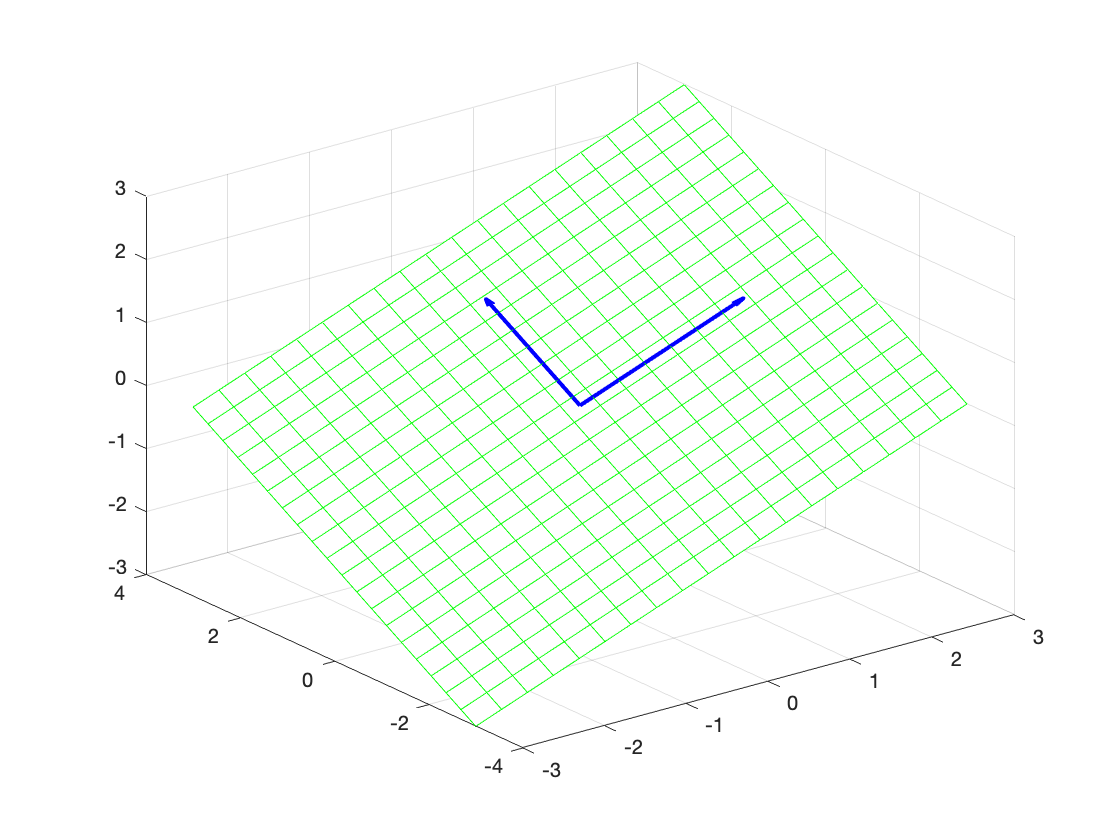

s=linspace(-1.5,1.5,20);
t=linspace(-1.5,1.5,20);
[S,T]=meshgrid(s,t);
X=2*S; Y=2*T; Z=S+T;
mesh(X,Y,Z,'EdgeColor','g')
hold on
quiver3(0,0,0,2,0,1,0,'LineWidth',2,'Color','b')
quiver3(0,0,0,0,2,1,0,'LineWidth',2,'Color','b')
hold off

They are definitely linearly independent because they are not parallel. Now, consider the vector 


$$\vec v_3=\pmatrix{1\cr 1\cr 3}$$


Let's add it to our image. 

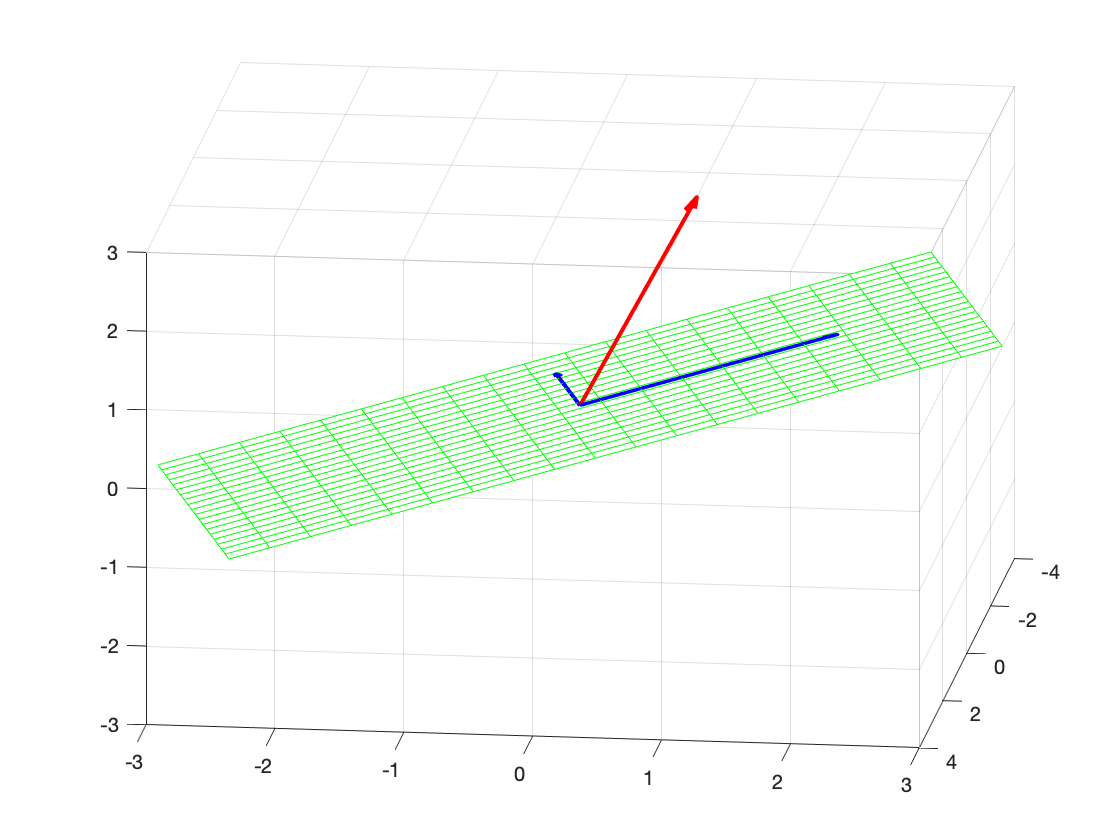

s=linspace(-1.5,1.5,20);
t=linspace(-1.5,1.5,20);
[S,T]=meshgrid(s,t);
X=2*S; Y=2*T; Z=S+T;
mesh(X,Y,Z,'EdgeColor','g')
hold on
quiver3(0,0,0,2,0,1,0,'LineWidth',2,'Color','b')
quiver3(0,0,0,0,2,1,0,'LineWidth',2,'Color','b')
quiver3(0,0,0,1,1,3,0,'LineWidth',2,'Color','r')
hold off
view(-7,-22)

The red vector $\vec v_3$ does not lie in the plane spanned by the blue vectors $\vec v_1$ and $\vec v_2$, so it cannot be written as a linear combination of $\vec v_1$ and $\vec v_2$. These three vectors are linearly independent.